# **Model Reduction Benchmarks**

We collected a set of problems related with model reduction for delay systems. Each section defines system parameters, matrices, delays and computes the reduced delay model of the original delay system. You can execute all the examples and compare the results with your own algorithms.

## Benchmarks

### Example 1: Heated Rod with order 100 [Example (i) in 1, p. 1416-1417]

% state matrix
n = 100;
x = sin(((0:(n-1))/(n-1))*pi);
Delta0 = diag(x);
A0 = ((n-1)/pi)^2*(diag(-2*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1)) -2*Delta0;

% state delay matrix
A1 = 2*fliplr(Delta0);

% input and output matrices
B = ones(n,1)/norm(ones(1,n));
C = B';

% delay
tau = 1;

% define delay system
sys = ssd(cat(3,A0,A1),[0 tau],B,0,C,0,[],[]);

Let's reduce the system order at first to 50 since we do not know beforehand what is the good reduction order.

% enable sparse computation option
opt = ssdoptions('Sparse',true);
[sysr50,info] = balred(sys,50,opt);
% figure; sigma(sys,sysr50)

Now, we can look at the state's energy contribution.

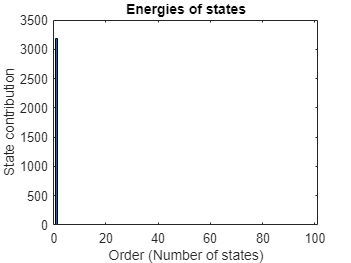

figure; plot(info)

As we can see, there is only one state with high energy. Let's try third order approximation since the other two states are small but non-zero and compare.

sysr3 = balred(sys,3,info);
% figure; sigma(sys,sysr3)

### Example 2: Mass-spring system with order 1000 [Example 5.1 in 2, p. 29-30]

% define system parameters and matrices
n = 1000; q = 100;
m = 1;      % mass
c = 0.2;     % damping
kappa = 1;  % spring stiffness

% state matrices
M_mech = diag(m*ones(1,n));
K_mech = diag([2*kappa*ones(1,n-1) kappa]) + diag(-kappa*ones(1,n-1),1) + diag(-kappa*ones(1,n-1),-1);
C_mech = diag([3*c*ones(1,n-1) 2*c]) + diag([-2*c repmat([-c -2*c],1,(n/2-1))],1) + diag([repmat([-2*c -c],1,(n/2-1)) -2*c],-1);

% state delay matrices
% Note: F_mech's and G_mech's dimensions in [2] are not consistent since
% (1,1) submatrix is not square. Appended with zeros to make it consistent.
F_mech = [[diag(0.3*ones(1,q)) zeros(q,1)] + [zeros(q,1) diag(-0.3*ones(1,q))] zeros(q,n-q-1);zeros(n-q,n)];
G_mech = [[diag(0.1*ones(1,q)) zeros(q,1)] + [zeros(q,1) diag(-0.1*ones(1,q))] zeros(q,n-q-1);zeros(n-q,n)];

% input and output matrices
B_input = [zeros(n-1,1); 1]; % external force
C_output = B_input';

% delay
tau = 2;

% convert matrices into standard form
A0 = [   zeros(n)           eye(n); 
        -M_mech\K_mech     -M_mech\C_mech];
A1 = [   zeros(n)           zeros(n);
        -M_mech\F_mech     -M_mech\G_mech];
B  = [zeros(n,1); M_mech\B_input];
C  = [C_output zeros(1,n)];

% define delay system in standard form
sys = ssd(cat(3,A0,A1),[0 tau],B,0,C,0,[],[]);

SSD cannot handle the size of this problem.

### Example 3: Platoon of eight vehicles with order 23 [Example in 3, p. 1416-1417]

% auxiliary matrices and parameters
n = 8;                  % number of vehicles
c = 0.25;               % engine time constant
ks = 0.875; kv = 2.5;   % tranmission gains between the vehicles
tau = 0.005;            % total delay

A_01 = [0 -c  0;
        0  0  c;
        0  0 -1];
A_02 = [0  c  0;
        0  0  0;
        0  0  0];
A_03 = [c  0;
        0  0;
        0  0];
A_04 = [  0  c;
        -kv -1];
A_11 = [ 0   0  0;
         0   0  0;
        ks -kv  0];
A_12 = [0  0 0;
        0  0 0;
        0 kv 0];
A_13 = [ 0  0;
         0  0;
        kv  0];

n_01 = size(A_01,1);
n_04 = size(A_04,1);

% state matrix
A0 = (1/c)*(blkdiag(kron(eye(n-1),A_01),A_04) + [zeros((n-1)*n_01,n_01) blkdiag(kron(eye(n-2),A_02),A_03);zeros(n_04,(n-1)*n_01+n_04)]);

% state delay matrix
A1 = (1/c)*(blkdiag(kron(eye(n-1),A_11),zeros(n_04)) + [zeros((n-1)*n_01,n_01) blkdiag(kron(eye(n-2),A_12),A_13);zeros(n_04,(n-1)*n_01+n_04)]);

% input and output matrices
B = [zeros(1,(n-1)*n_01) 0 kv/c]';
C = [kron(ones(1,(n-1)),[1 0 0]) 0 0];

% define delay system
sys = ssd(cat(3,A0,A1),[0 tau],B,0,C,0,[],[]);

Reduce the system order at first to 10 since we do not know beforehand what is the good reduction order.

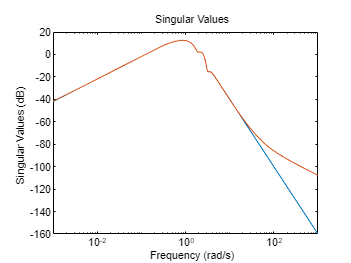

[sysr10,info] = balred(sys,10);
opt=sigmaoptions;
opt.XLim = [1e-3 1e3];
figure;sigma(sys,sysr10,opt)

Let's check the state's energy contribution.

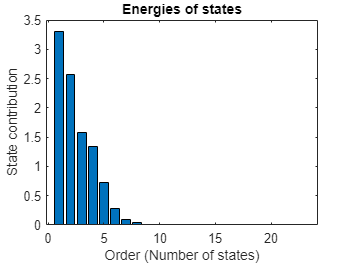

figure; plot(info)

The order 9 seems enough to capture the dynamics.

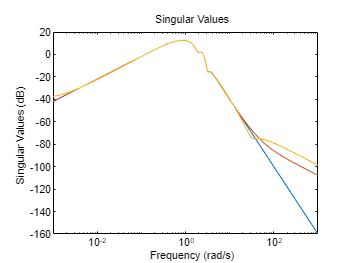

sysr9 = balred(sys,9,info);
figure; sigma(sys,sysr10,sysr9,opt)

### Example 4: Synthetic example with order 6 [Example 1 in 4, p. 6-7]

% state matrix
A0 = [-0.91 -0.62  1.61  0.06  0.27  0.38
       0.11 -0.18 -0.51  0.04  0.02 -0.08
       0.05  0.03 -0.18  0.02  0.06  0.17
       0.02  0.29  1.63 -0.80 -0.16  0.05
      -0.10 -0.21  0.01  0.14 -0.11  0.25
      -0.03  0.46 -0.49 -0.03 -0.12 -1.11];

% state delay matrix
A1 = [ 0.74  0.66 -0.34 -0.21 -0.21  0.23
      -0.14 -0.26  0.24  0.11  0.21  0.07
       0.09  0.04 -0.37  0.05 -0.01 -0.06
      -0.35  0.01 -1.01 -0.38 -0.71 -0.65
       0.39  0.20 -0.12  0    -0.08  0.15
      -0.75 -0.33  1.26  0.07  0.40  0.01];

% input and output matrices
B  = [ 0.61 -0.11  0.14  0.31  0.13 -0.27]';
C0 = [ 3.2  -1    29.5   2     8.4   8.5 ];
C1 = [-4.5 -38.2  -6.5  -5.6   1.7   2];
D = 0.3;

% delay
tau = 1.6;

% define delay system
sys = ssd(cat(3,A0,A1),[0 tau],B,0,cat(3,C0,C1),[0 tau],D,0);

Since the order is small, we can first obtain the balanced realization and plot the info

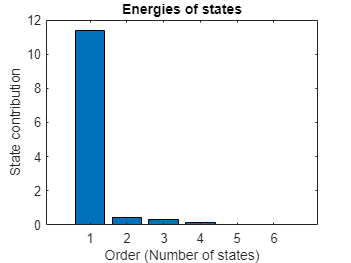

[sysb,info] = balreal(sys);
figure; plot(info)

The energy contributions of the states tell us that the orders 2, 3, 4 are good candidates

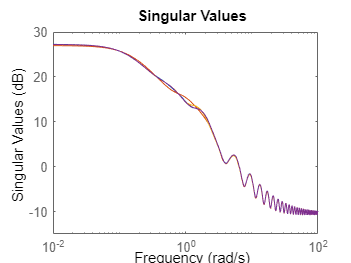

sysr2 = balred(sys,2,info);
sysr3 = balred(sys,3,info);
sysr4 = balred(sys,4,info);
figure; sigma(sys,sysr2,sysr3,sysr4);

The 4th order system is almost same as the original system. Depending on the requirements, 2nd and 3rd orders may be acceptable as well.

### Example 5: Second-order system with proportional damping with order 2000 [Example 1 in 5, p. 134-135]

% system parameters
n = 2000; q = 80;
alpha = 0.05; beta = 0.05; % damping parameters

% state matrices
M = diag((2/sqrt(1-alpha*beta))*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1);
M(1,1) = M(1,1)+1; M(end,end) = M(end,end)+1;
K = diag((2/sqrt(1-alpha*beta))*ones(1,n)) + diag(-1*ones(1,n-1),1) + diag(-1*ones(1,n-1),-1);
K(1,1) = K(1,1)-1; K(end,end) = K(end,end)-1;
K = (alpha/beta)*K;
G = alpha*M+beta*K;

% state delay matrices
E = blkdiag(diag(0.5*ones(1,q)) + diag(0.1*ones(1,q-1),1) + diag(0.1*ones(1,q-1),-1),zeros(n-q));
F = 2*E-0.4*eye(n);

% input and output matrices
B = [1; zeros(n-1,1)];
C = B';

% convert matrices into standard form
A0 = [ zeros(n) eye(n); 
        -M\K     -M\G];
A1 = [ zeros(n) zeros(n);
        -M\F     -M\E];
B0  = [zeros(n,1); M\B];
C0  = [C zeros(1,n)];
tau = 1;

% define delay system in standard form
sys = ssd(cat(3,A0,A1),[0 tau],B0,0,C0,0,[],[]);

SSD cannot handle the size of this problem.

## References

- W. Michiels et al. [Krylov-Based Model Order Reduction of Time-Delay Systems](https://doi.org/10.1137/100797436), 2011.

- M. Saadvandi et al. [On dominant poles and model reduction of second order time-delay systems](https://www.sciencedirect.com/science/article/abs/pii/S0168927411001681), 2012.

- G. Scarciotti et al. [Model Reduction by Moment Matching for Linear Time-Delay Systems](https://doi.org/10.3182/20140824-6-ZA-1003.00655), 2014.

- S. N. Lordejani et al. [Model order reduction for linear time delay systems: delay-dependent approach based on energy functionals](https://doi.org/10.1016/j.automatica.2019.108701), 2020.

- Y.-L. Jiang et al. [Structure preserving model reduction of second-order time-delay systems via approximate Gramians](https://doi.org/10.1049/iet-cds.2019.0107), 2020.